#### Práctica 1

# Reconocimiento de posiciones de ajedrez

- Obtención del dataset de imágenes de: [https://www.chess.com/home](https://www.chess.com/home) 

- Primer análisis de imágenes de prueba

# Imagen de ejemplo:

- Un peón blanco sobre casilla blanca

### 1º Cargar la imagen

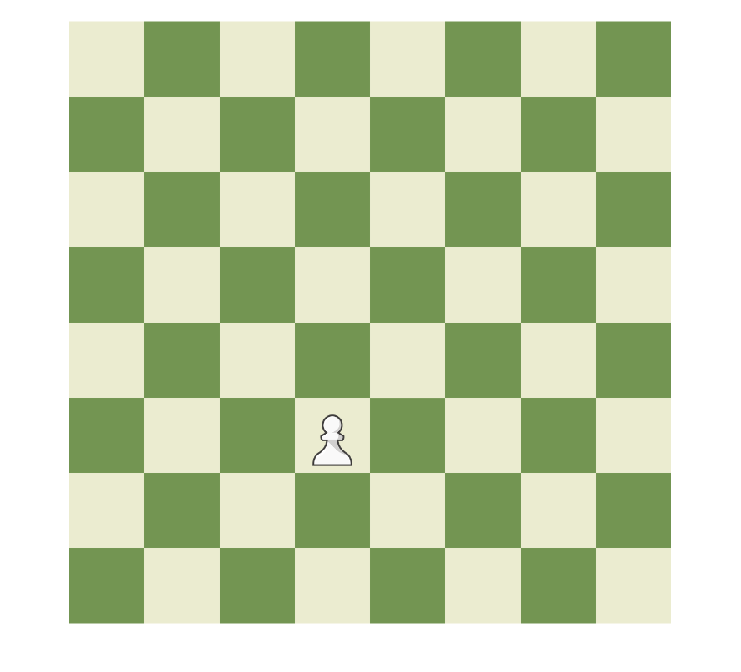

board_1 = imread("board_1.png");
imshow(board_1);

### 2º Paso a grises

Puesto que hay piezas blancas y negras, y casillas blancas y verdes no está claro si utilizar la imágen en blanco y negro facilitará o dificultará la tarea de reconocimiento de piezas. Por ejemplo, una pieza blanca sobre una casilla blanca sería más dificil de reconocer. 

gray_board_1 = im2gray(board_1);

### 3º Binarización

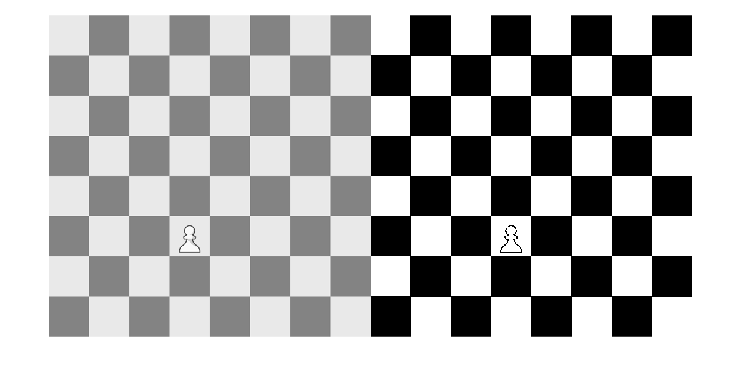

binary_board_1 = imbinarize(gray_board_1);
montage({gray_board_1,binary_board_1});

### 4º Resta del tablero vacío

Cargamos el tablero vacío y lo binarizamos al igual que con `board_1`

board_gray = imread("board_0.png");
gray_board = im2gray(board_gray);
binary_board = imbinarize(gray_board);

Restamos para obtener la pieza sola:

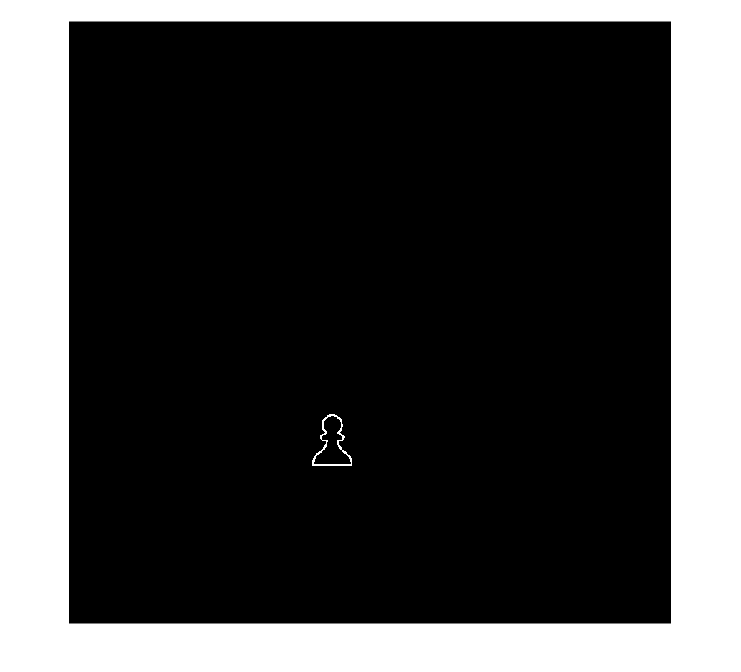

pieces =  binary_board - binary_board_1;
imshow(pieces);

Se ha invertido la silueta del peón que antes era negra, ahora es blanca sobre un fondo negro, por lo que se ve bastante bien.    

### 5º Rellenamos la pieza

Usando `imfill()`

% Rellenar los agujeros en las piezas detectadas
filled_piece = imfill(pieces, 'holes');

### 6º Etiquetado y análisis de regiones

Con:

- `bwlabel()`

- `regionprops()`

% Etiquetado y análisis de regiones
[labeled_image, num_pieces] = bwlabel(filled_piece);
stats = regionprops(labeled_image, 'Area', 'Centroid');

display(stats)

stats = struct with fields:
        Area: 1769
    Centroid: [315.3968 506.8999]


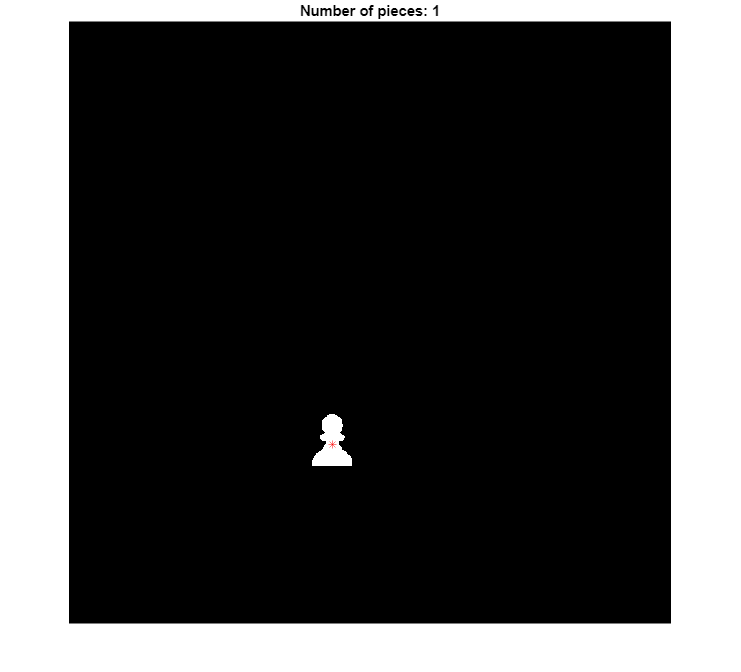


% Mostrar resultados
imshow(filled_piece);
title(['Number of pieces: ', num2str(num_pieces)]);

% Opcional: Visualizar centroides de las piezas
hold on;
for k = 1:num_pieces
    plot(stats(k).Centroid(1), stats(k).Centroid(2), 'r*');
end
hold off;

Observamos que aunque el peón es blanco sobre una casilla blanca, como tiene una silueta negra se ha podido identificar y rellenar. No obstante este proceso no es aplicable a piezas negras sobre casillas negras...

# Imagen de ejemplo:

- Un peón negro sobre casilla negra

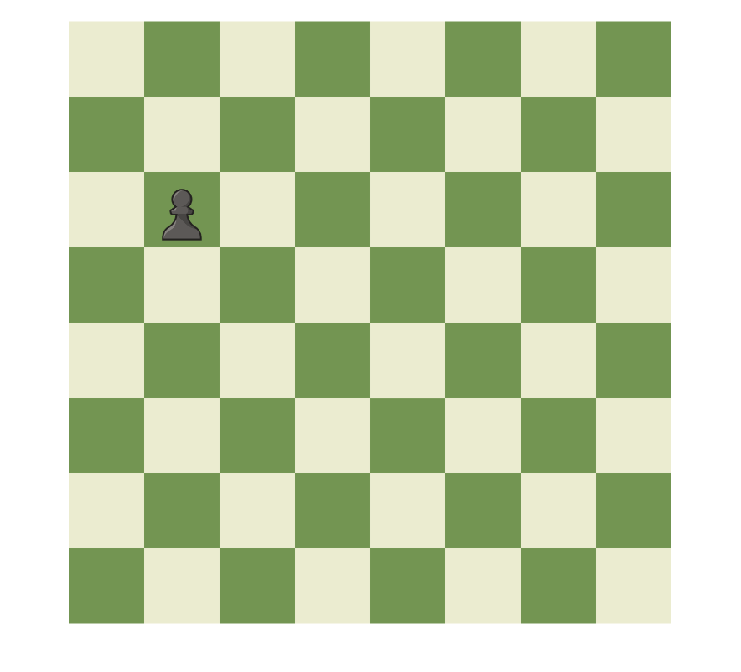

board_2 = imread("board_2.png");
imshow(board_2);

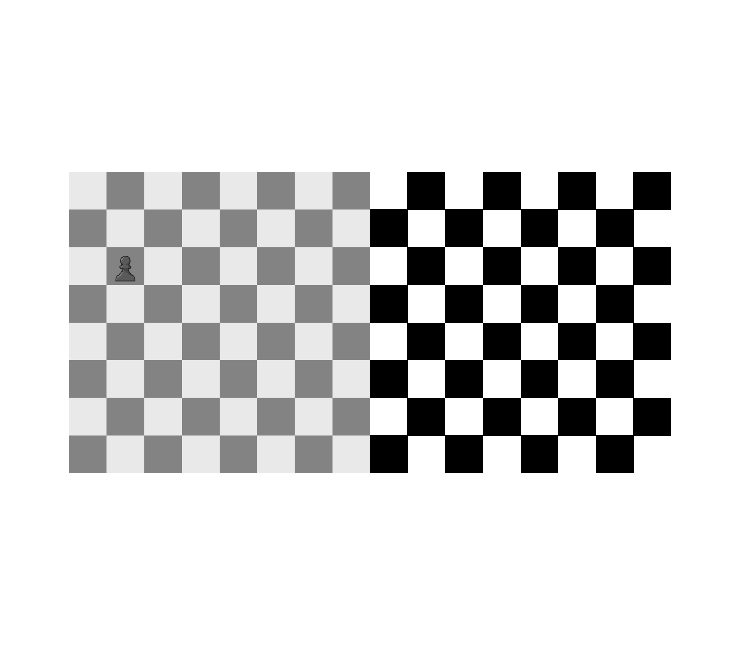


gray_board_2 = im2gray(board_2);
binary_board_2 = imbinarize(gray_board_2);

montage({gray_board_2, binary_board_2});

#### PROBLEMA: al binarizar no reconoce el peón negro sobre fondo negro!!

Posible soluciones:

- Binarizar con un threshold haciendo que las casillas negras (que en realidad son verdes) se binaricen a blanco y no negro. 

- Usando sensibilidad en la binarización

Y así evitamos también tener que hacer la resta del tablero vacío.

- Con un ejemplo de muchas piezas

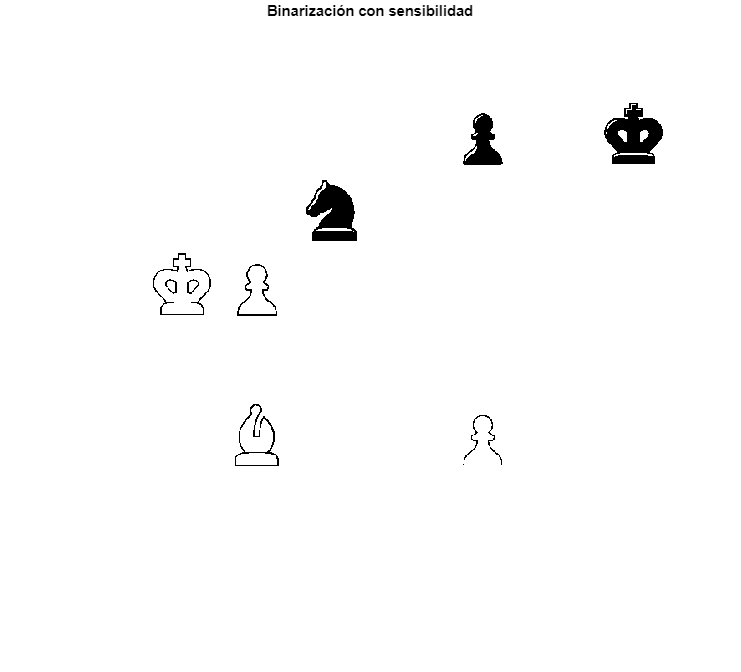

board_0 = imread("manyPieces.png");

gray_board = im2gray(board_0);

% Binariar con sensibilidad
binary_board = imbinarize(gray_board,0.4);
imshow(binary_board);
title('Binarización con sensibilidad')

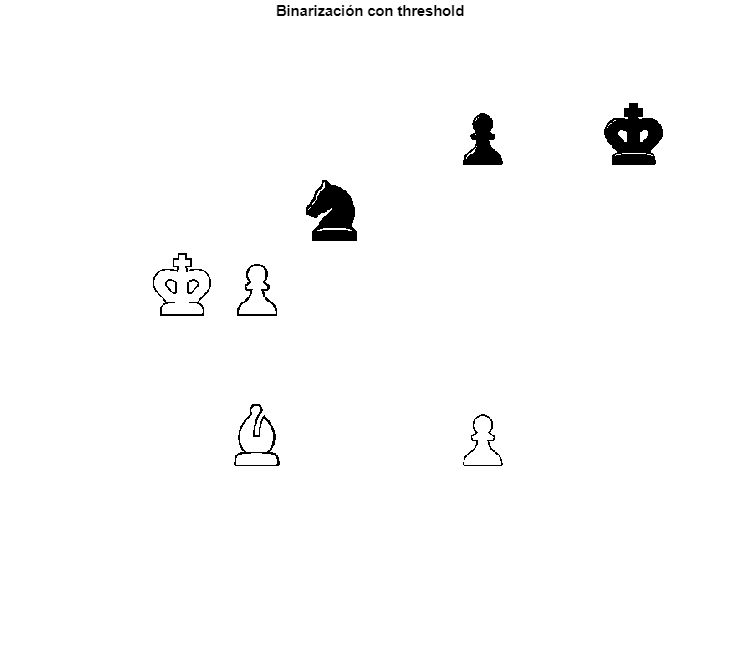

% Binarizar con threshold
binary_board = gray_board > 128; % si es mayor que 128 -> 255 (blanco)
                                     % si es menor o igual -> 0 (negro)+

imshow(binary_board);
title('Binarización con threshold')

De ambas maneras, este proceso sí es aplicable a más piezas.

### Operaciones morfológicas sobre las piezas

brush = strel("square",4);

Utilizaremos la imagen anterior con varias piezas sobre el tablero.

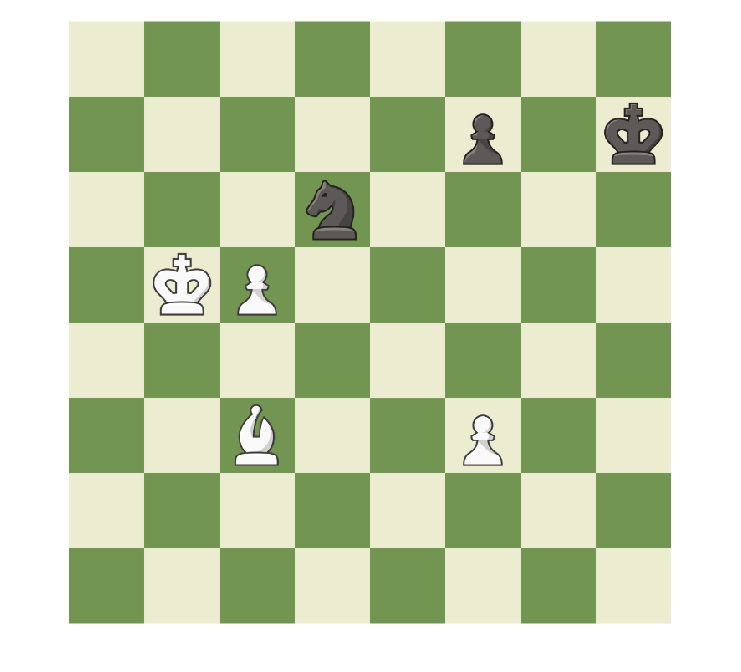

imshow(board_0);

#### Dilatación vs erosión

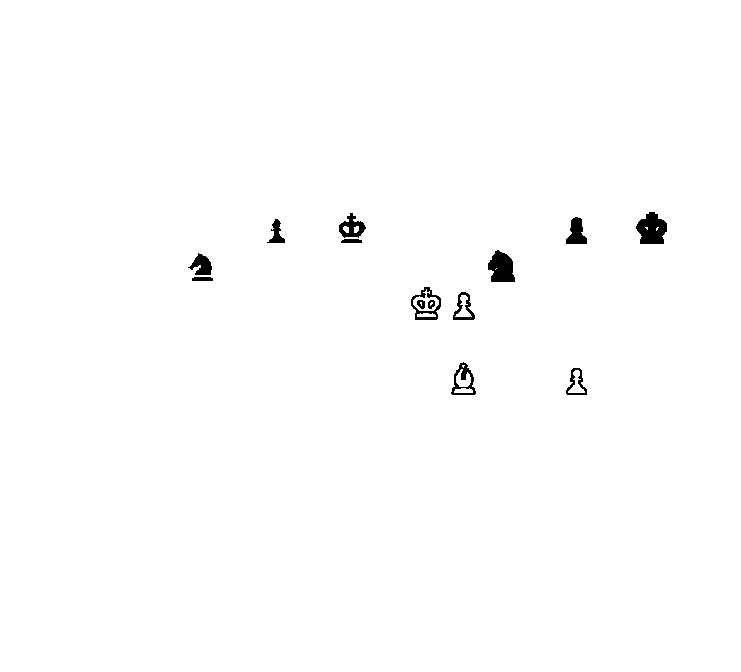

board_DILATE = imdilate(binary_board,brush);
board_ERODE = imerode(binary_board,brush);
montage({board_DILATE,board_ERODE});

#### OPEN vs CLOSE

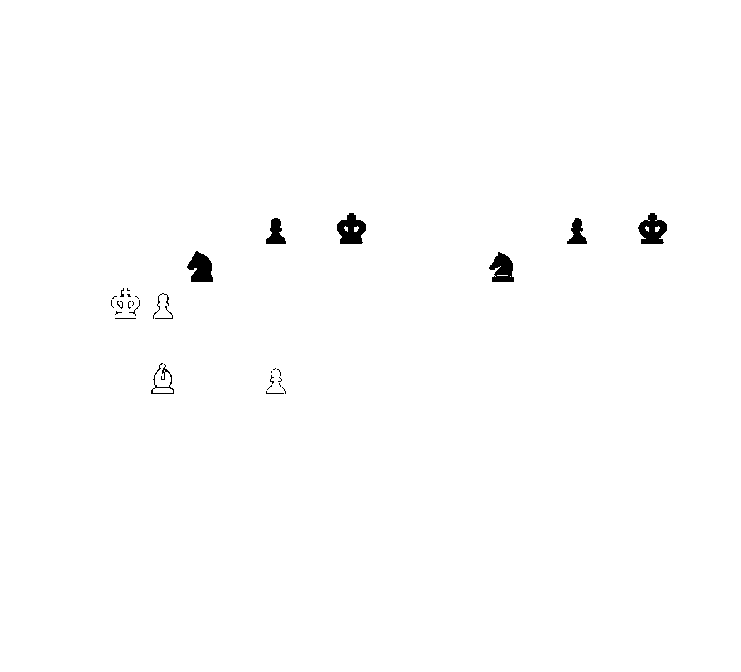

board_OPEN = imopen(binary_board,brush);
board_CLOSE = imclose(binary_board,brush);
montage({board_OPEN,board_CLOSE});

#### OPEN-CLOSE vs CLOSE-OPEN

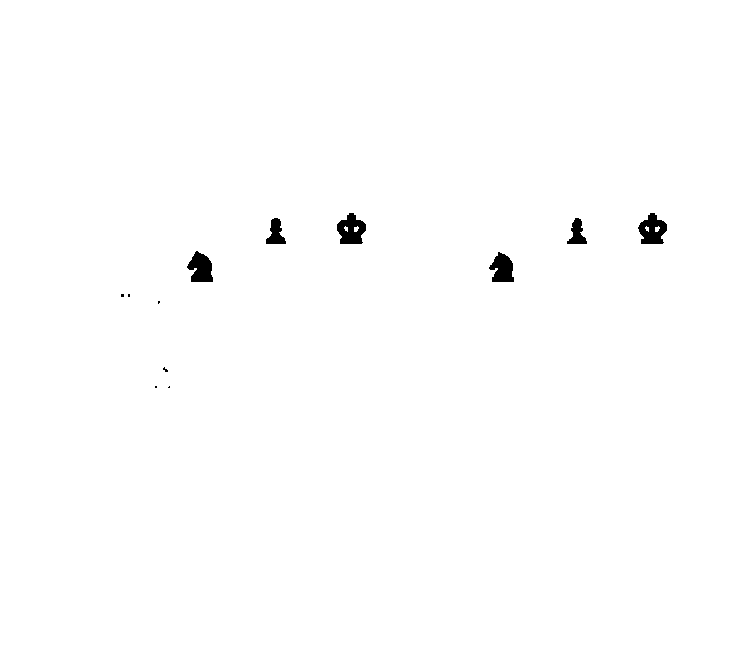

board_OC = imclose(board_OPEN,brush);
board_CO = imopen(board_CLOSE,brush);
montage({board_OC,board_CO});

Observamos que para las piezas blancas desaparecen tras algunas operaciones morfológicas.

La operación de `OPEN `o apertura es la única que para ambos tipos (blanco y negro) trabaja bien. El threshold ha evitado que las piezas negras desaparezcan sobre las casillas negras sin embargo...

#### PROBLEMA: piezas blancas desaparecen tras O.Morfológicas!!

Se debe a que su silueta negra es demasiado fina en comparación con el grosor de silueta de las piezas negras.

Esto indica que debemos hacer las operaciones morfológicas DESPUÉS de que las piezas estén rellenas.

Ahora hay 2 opciones antes de rellenar las piezas:

### Método 1: 

- Paso a gris

- Resto el tablero vacío

- Binarizo

- Relleno

Utilizaré para la resta una imagen del tablero vacío

board_0 = imread("board_0.png");
gray_board = im2gray(board_0);

Y otra imagen con el tablero con varias piezas:

% Cargar la imágen y pasarlas a escala de grises
board_x = imread("manyPieces.png");
gray_board_x = im2gray(board_x);

Para obtener las piezas realizo la resta:

% Para obtener la piezas
pieces = gray_board - gray_board_x;

% Binarización
imbin = imbinarize(pieces);

% Relleno de huecos
im_filled = imfill(imbin,"holes");

Muestro las imágenes resultantes:

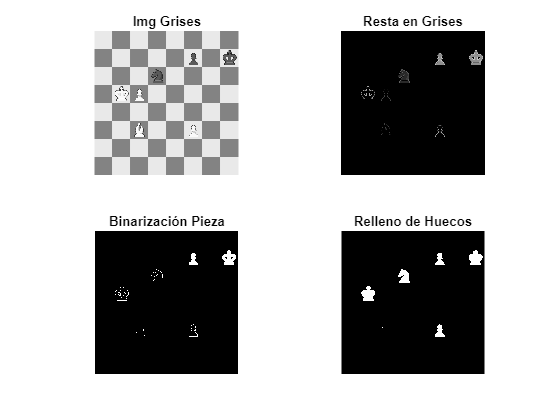

figure
% Mostrar la imagen original en escala de grises
subplot(2, 2, 1);
imshow(gray_board_x);
title('Img Grises');

% Mostrar la resta en escala de grises
subplot(2, 2, 2);
imshow(pieces);
title('Resta en Grises');

% Mostrar la imagen binarizada
subplot(2, 2, 3);
imshow(imbin);
title('Binarización Pieza');

% Mostrar la imagen con los huecos rellenados
subplot(2, 2, 4);
imshow(im_filled);
title('Relleno de Huecos');
hold off

#### PROBLEMA: la diferencia binarizada resulta en color negro!!

Las piezas blancas sobre casillas negras se desvanecen en la binarización, parece que binarizar una resta de piezas en escala de grises hace que el color resultante sea binarizado a negro.

Añadiendo menor sensibilidad a la binarización ya funcionaría.

Para valores menores que 0.3 

% Binarización
imbin = imbinarize(pieces,0.2);

% Relleno de huecos
im_filled = imfill(imbin,"holes");

Muestro las imágenes resultantes:

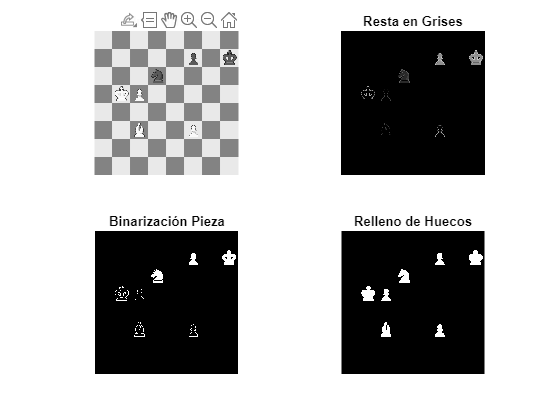

figure
% Mostrar la imagen original en escala de grises
subplot(2, 2, 1);
imshow(gray_board_x);
title('Img Grises');

% Mostrar la resta en escala de grises
subplot(2, 2, 2);
imshow(pieces);
title('Resta en Grises');

% Mostrar la imagen binarizada
subplot(2, 2, 3);
imshow(imbin);
title('Binarización Pieza');

% Mostrar la imagen con los huecos rellenados
subplot(2, 2, 4);
imshow(im_filled);
title('Relleno de Huecos');
hold off

### Método 2:

- Binarización inversa con sensibilidad `0.5`

- Relleno

Con varias piezas

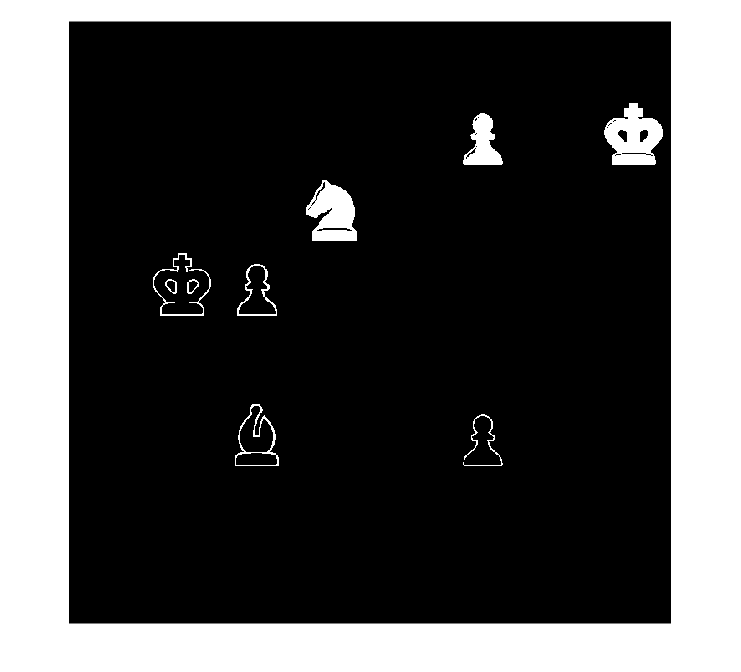

board_x = imread("manyPieces.png");
gray_board_x = im2gray(board_x);

bin_board_x = ~imbinarize(gray_board_x,0.5);
figure
imshow(bin_board_x);
hold off

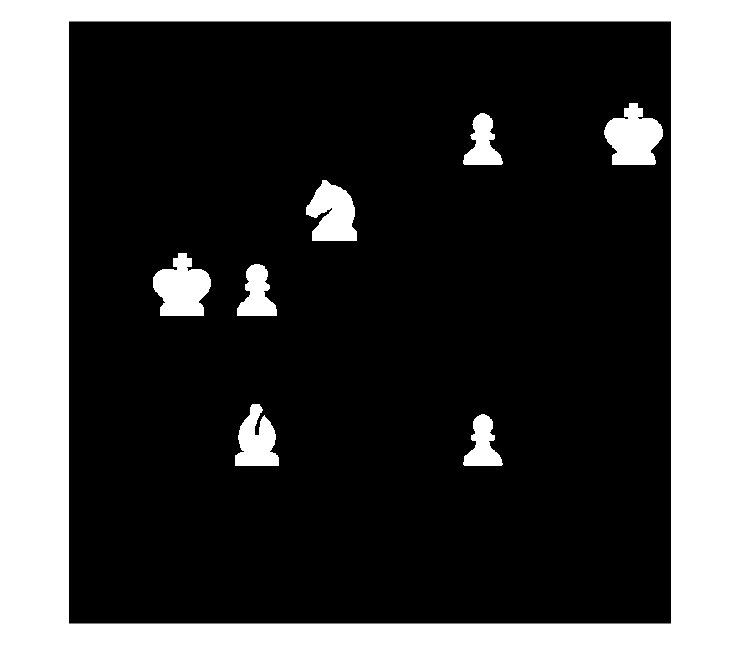

filled_board_x = imfill(bin_board_x,"holes");
figure
imshow(filled_board_x)
hold off

Por este método obtenemos todas las piezas rellenas de manera más rápida y sin necesitar hacer una resta. Gracias a que las piezas blancas tienen una silueta negra.

### 6º Etiquetado y análisis de regiones

Con:

- `bwlabel()`

- `regionprops()`

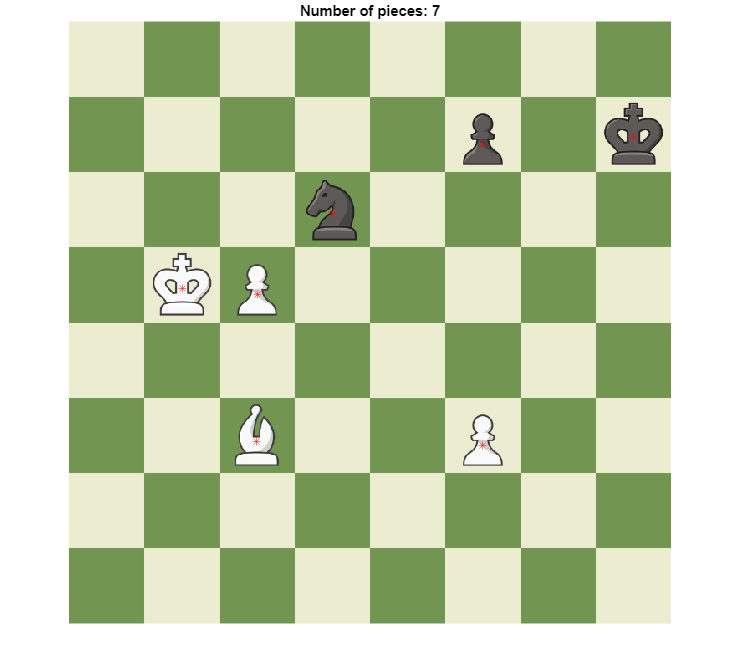

% Etiquetado y análisis de regiones
[labeled_image, num_pieces] = bwlabel(filled_board_x);
stats = regionprops(labeled_image, 'Area', 'Centroid');

% Mostrar resultados
imshow(board_x);
title(['Number of pieces: ', num2str(num_pieces)]);

% Opcional: Visualizar centroides de las piezas
hold on;
for k = 1:num_pieces
    plot(stats(k).Centroid(1), stats(k).Centroid(2), 'r*');
end
hold off;

Con este código ya podemos identificar el número de piezas en el tablero, no obstante, también queremos clasificar cada pieza (peón,caballo,alfil,torre,rey,reina).

Para ello:

- Las áreas de piezas de un mismo tipo deben ser lo más parecido posible.

- Las áreas de piezas de distinto tipo deben ser lo más distintas posibles.

Según el área de cada pieza (con un rango de tolerancia) se puede conocer qué pieza es cada región encontrada.

Con un tablero que contiene todas las piezas vamos a establecer rangos de áreas.

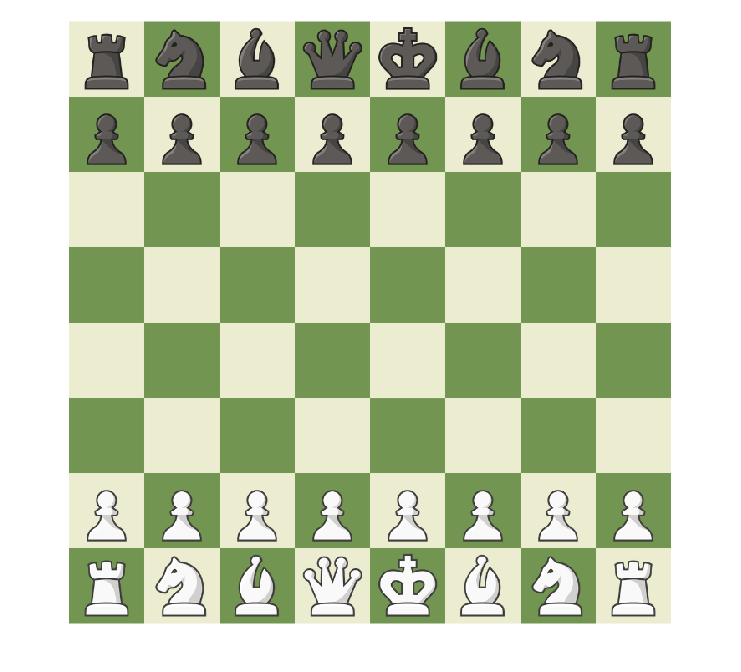

board_full = imread("full.png");
imshow(board_full);

### Aplicación de operaciones morfológicas:

Tras varias pruebas, la operación siguiente es la que facilita los 2 puntos:

- Las áreas de piezas de un mismo tipo deben ser lo más parecido posible.

- Las áreas de piezas de distinto tipo deben ser lo más distintas posibles.

brush = strel('disk', 2);

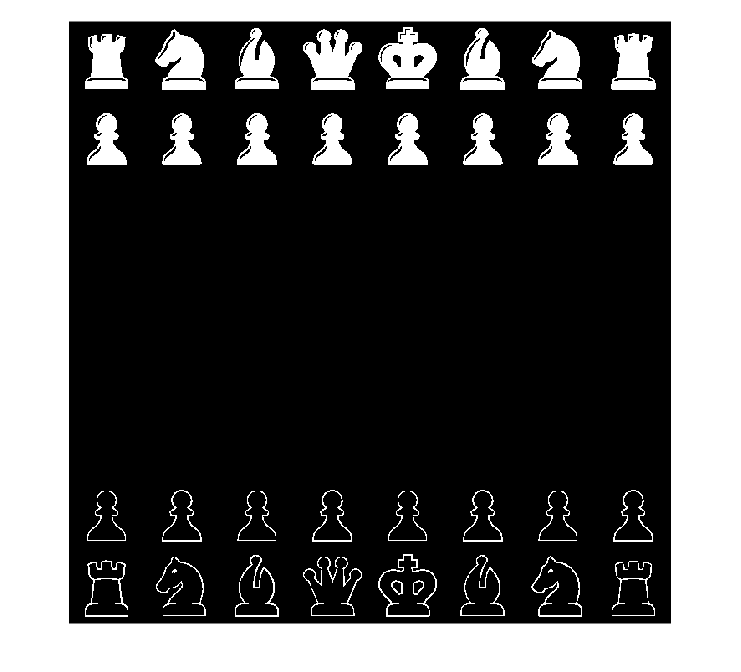

gray_board_full = im2gray(board_full);

bin_board_full = ~imbinarize(gray_board_full,0.4);
imshow(bin_board_full);

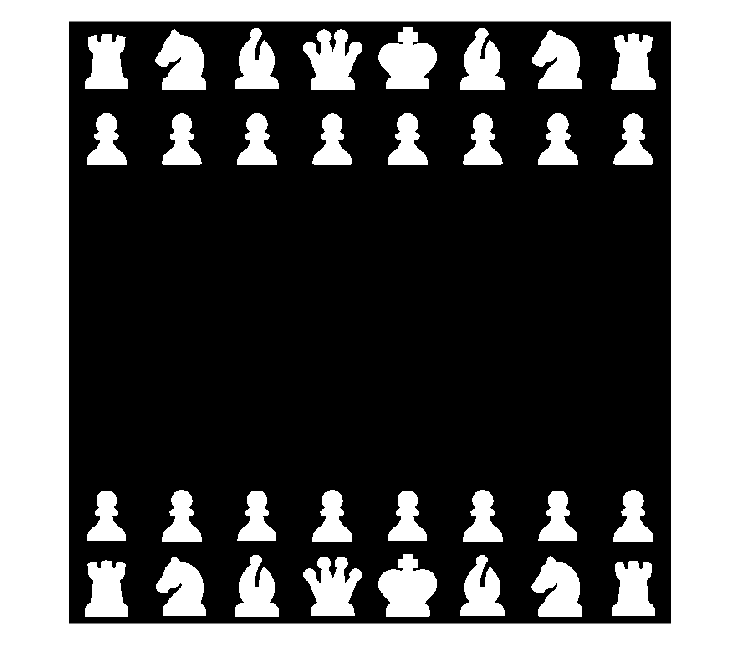


filled_board_full = imfill(bin_board_full,"holes");
imshow(filled_board_full);

La siguiente operación morfológica ... permite una mayor precisión en la clasificación.

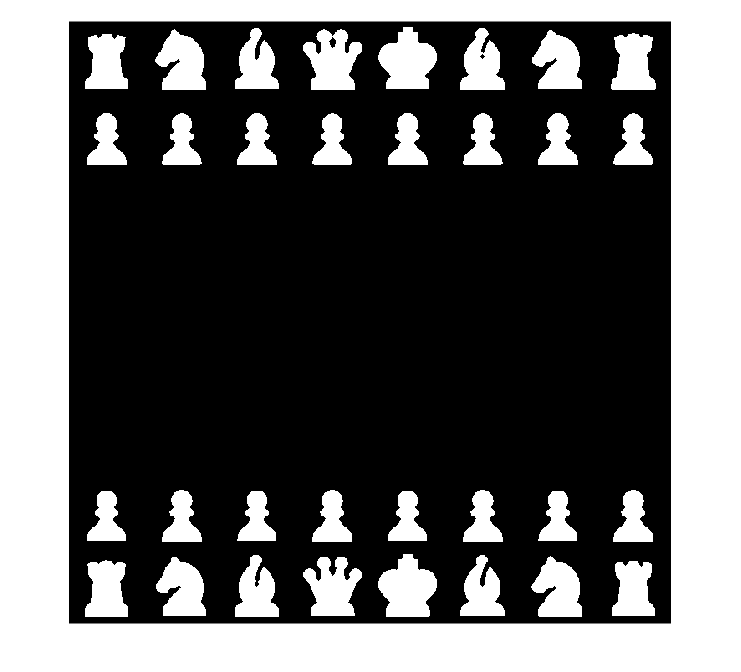

full_open = imclose(filled_board_full,brush);

imshow(full_open);

% Etiquetado y análisis de regiones
[labeled_image, num_pieces] = bwlabel(full_open);
% Obtener las propiedades de las regiones
stats = regionprops(labeled_image, 'Area', 'Centroid');

display(stats)

stats = 32×1 struct array with fields:
    Area
    Centroid


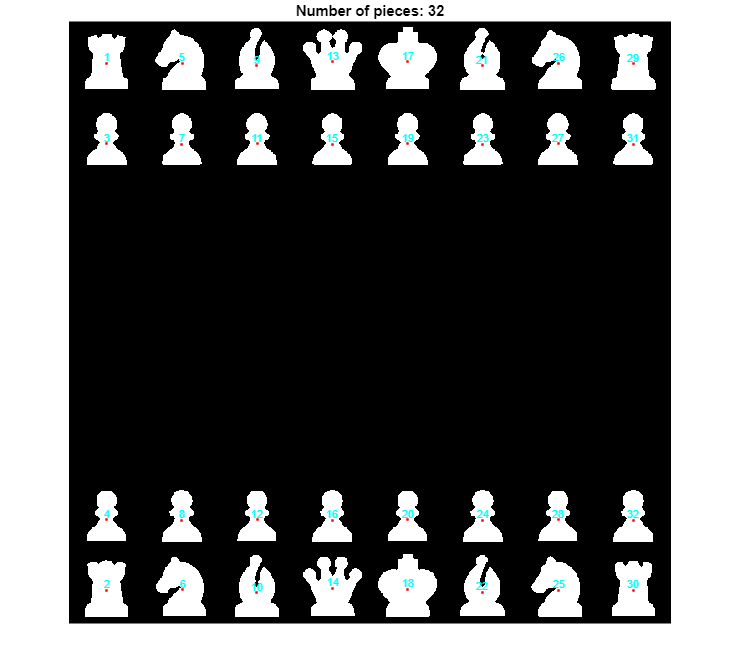


% Mostrar resultados
imshow(full_open);
title(['Number of pieces: ', num2str(num_pieces)]);

% Visualizar centroides de las piezas
hold on;
for k = 1:num_pieces
    plot(stats(k).Centroid(1), stats(k).Centroid(2), 'r.');
    % Añadir un número al centroide
    text(stats(k).Centroid(1), stats(k).Centroid(2), num2str(k), 'Color', 'cyan', ...
         'FontSize', 8, 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom');
end
hold off;

Tras un análisis de áreas obtenemos los rangos de áreas:

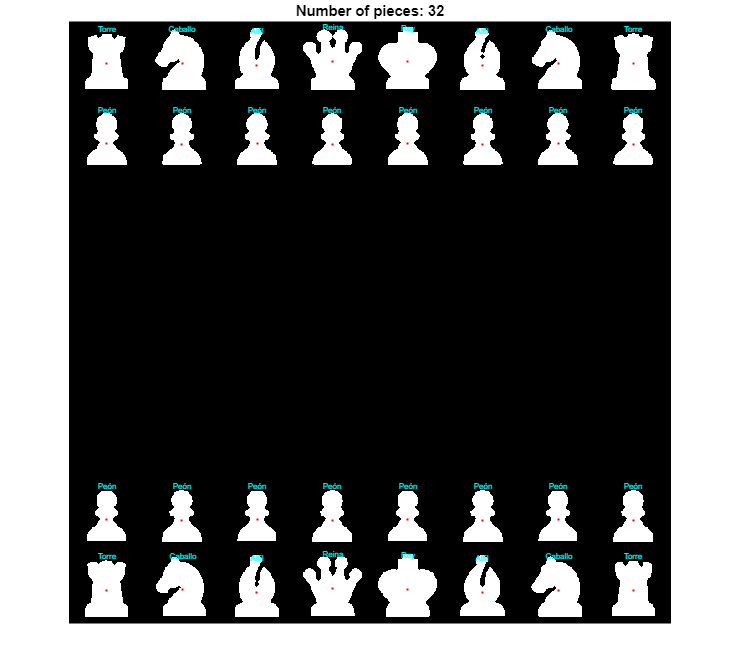

% Inicializar la celda para almacenar los nombres de las piezas
pieceNames = cell(num_pieces, 1); % Preallocar espacio para los nombres de las piezas

% Asignar el tipo de pieza basado en el área
for k = 1:num_pieces
    area = stats(k).Area; % Obtener el área de la región actual
    
    % Determinar el tipo de pieza según el área
    if area >= 1000 && area <= 1800
        pieceNames{k} = 'Peón';
    elseif area >= 2300 && area <= 2575
        pieceNames{k} = 'Alfil';
    elseif area >= 2576 && area <= 2800
        pieceNames{k} = 'Torre';
    elseif area >= 2801 && area <= 3050
        pieceNames{k} = 'Caballo';
    elseif area >= 3200 && area <= 3400
        pieceNames{k} = 'Reina';
    elseif area >= 3500 && area <= 3700
        pieceNames{k} = 'Rey';
    else
        pieceNames{k} = 'desconocido'; % Para áreas que no coinciden con ningún tipo
    end
end

% Añadir la columna 'Pieza' a la estructura stats
for k = 1:num_pieces
    stats(k).Pieza = pieceNames{k}; % Añadir el nombre de la pieza
end

% Mostrar la imagen
imshow(full_open);
title(['Number of pieces: ', num2str(num_pieces)]);
hold on; % Mantener la imagen actual para dibujar sobre ella

% Iterar a través de cada región para plotear los centroides y los nombres de las piezas
for k = 1:num_pieces
    % Marcar el centroide
    plot(stats(k).Centroid(1), stats(k).Centroid(2), 'r.', 'MarkerSize', 5);
    
    % Añadir el nombre de la pieza al centroide
    text(stats(k).Centroid(1), stats(k).Centroid(2)-35, stats(k).Pieza, 'Color', 'cyan', ...
         'FontSize', 6, 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom');
end

hold off; % Liberar la figura


% Extraer las columnas relevantes en una tabla
resultTable = table([stats.Area]', pieceNames, 'VariableNames', {'Area', 'Pieza'});

% Mostrar la tabla resultante
resultTable

resultTable = 32×2 table
    Area       Pieza   
    ____    ___________

    2621    {'Torre'  }
    2726    {'Torre'  }
    1781    {'Peón'   }
    1659    {'Peón'   }
    3032    {'Caballo'}
    2885    {'Caballo'}
    1719    {'Peón'   }
    1763    {'Peón'   }
    2423    {'Alfil'  }
    2522    {'Alfil'  }
    1781    {'Peón'   }
    1659    {'Peón'   }
    3391    {'Reina'  }
    3202    {'Reina'  }
    1719    {'Peón'   }
    1763    {'Peón'   }


Ajustando los rangos de cada área se obtiene una correcta clasificación.

Además creamos las funciones para no repetir el código y poder clasificar las piezas de cualquier imagen de tablero.

- `PieceClassifier.m`

[stats, labeled_image, num_pieces] = pieceClassifier(brush,board_full);

### Representaciones de resultados:

- Imagen con etiquetas

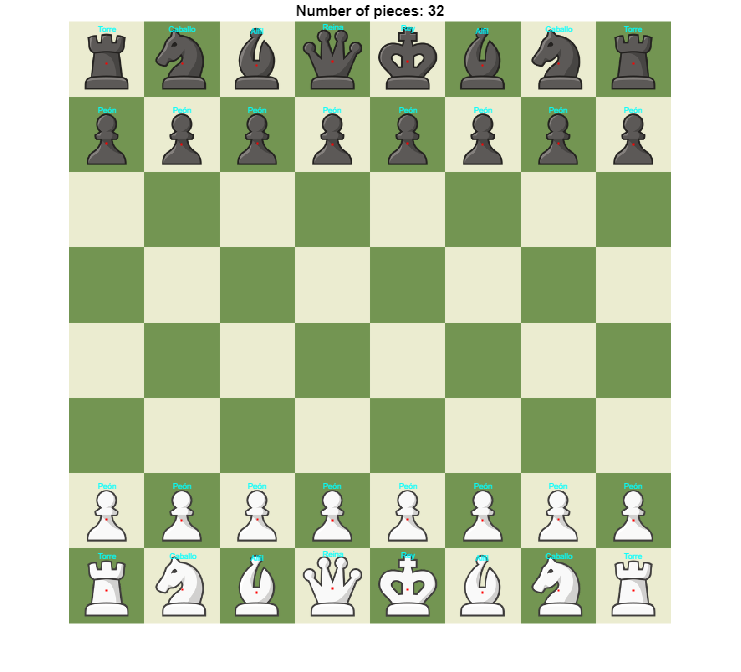

% Mostrar la imagen
imshow(board_full);
title(['Number of pieces: ', num2str(num_pieces)]);
hold on; % Mantener la imagen actual para dibujar sobre ella
    
% Iterar a través de cada región para plotear los centroides y los nombres de las piezas
for k = 1:num_pieces
        % Marcar el centroide
        plot(stats(k).Centroid(1), stats(k).Centroid(2), 'r.', 'MarkerSize', 5);
        
        % Añadir el nombre de la pieza al centroide
        text(stats(k).Centroid(1), stats(k).Centroid(2)-35, stats(k).Pieza, 'Color', 'cyan', ...
             'FontSize', 6, 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom');
end
    
hold off; % Liberar la figura

- Imagen con color

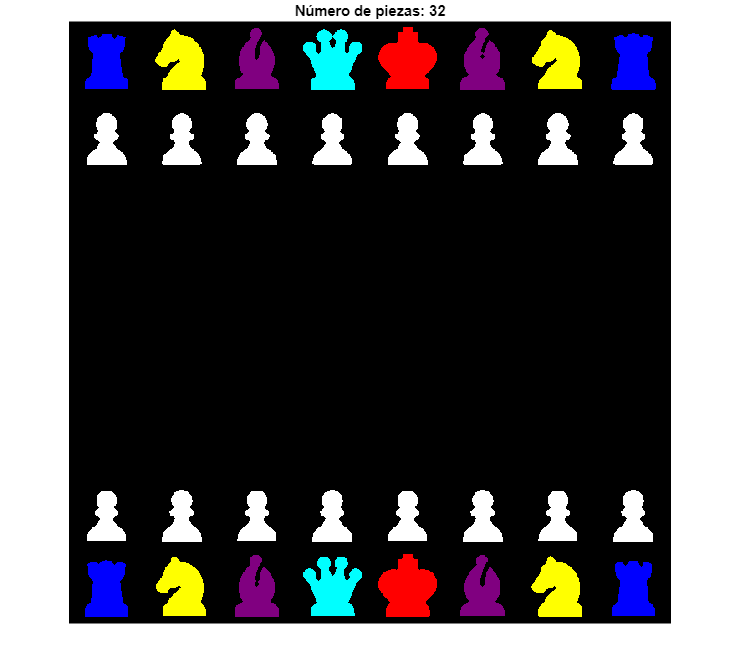

% Definir colores específicos para cada tipo de pieza
color_peon = [1, 1, 1];        % Blanco
color_alfil = [0.5, 0, 0.5];   % Morado
color_torre = [0, 0, 1];       % Azul
color_caballo = [1, 1, 0];     % Amarillo
color_reina = [0, 1, 1];       % Cyan
color_rey = [1, 0, 0];         % Rojo
color_desconocido = [0, 0, 0]; % Negro para piezas desconocidas

% Inicializar el arreglo para almacenar los colores
pieceColors = zeros(num_pieces, 3);

% Asignar colores basados en 'Pieza'
for k = 1:num_pieces
    switch stats(k).Pieza
        case 'Peón'
            pieceColors(k, :) = color_peon;
        case 'Alfil'
            pieceColors(k, :) = color_alfil;
        case 'Torre'
            pieceColors(k, :) = color_torre;
        case 'Caballo'
            pieceColors(k, :) = color_caballo;
        case 'Reina'
            pieceColors(k, :) = color_reina;
        case 'Rey'
            pieceColors(k, :) = color_rey;
        otherwise
            pieceColors(k, :) = color_desconocido;
    end
end

% Crear la imagen en color usando labeled_image
coloredImage = zeros(size(labeled_image, 1), size(labeled_image, 2), 3);

% Colorear cada pieza en función de su etiqueta
for k = 1:num_pieces
    color = pieceColors(k, :);
    mask = labeled_image == k;
    
    % Asignar el color en cada canal
    coloredImage(:,:,1) = coloredImage(:,:,1) + mask * color(1);
    coloredImage(:,:,2) = coloredImage(:,:,2) + mask * color(2);
    coloredImage(:,:,3) = coloredImage(:,:,3) + mask * color(3);
end

% Mostrar la imagen coloreada
imshow(coloredImage);
title(['Número de piezas: ', num2str(num_pieces)]);

- Superposición de color

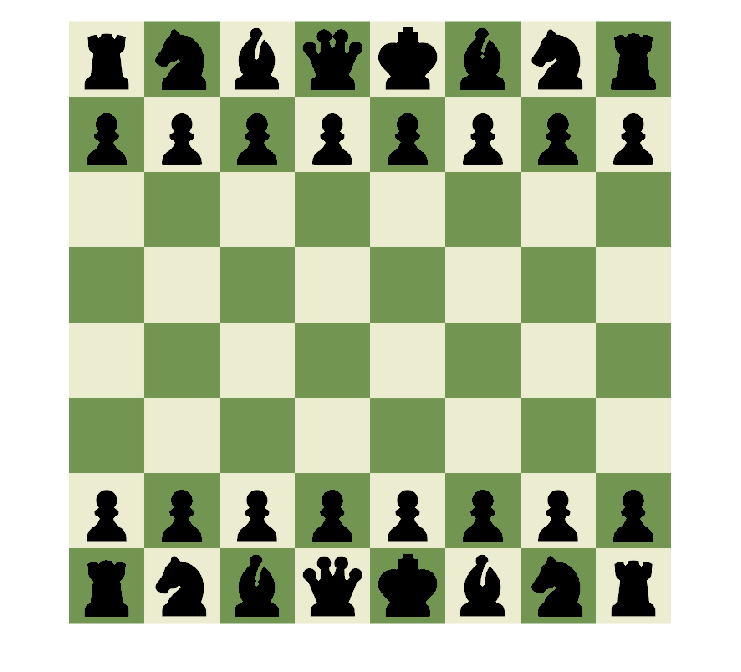

% Crear una máscara para las regiones que deseas eliminar
% Aquí puedes usar un criterio, como el área mínima, para seleccionar las regiones
mask = labeled_image > 0;  % Máscara con todas las regiones etiquetadas

% Aplicar la máscara para eliminar las regiones en `board_full`
% Si quieres hacerlas negras, establece los valores en 0
board_full_reduced = board_full;  % Crear una copia de `board_full`
board_full_reduced(repmat(mask, [1 1 3])) = 0;  % Establecer en 0 las regiones etiquetadas

% Mostrar la imagen con las regiones eliminadas
imshow(board_full_reduced);

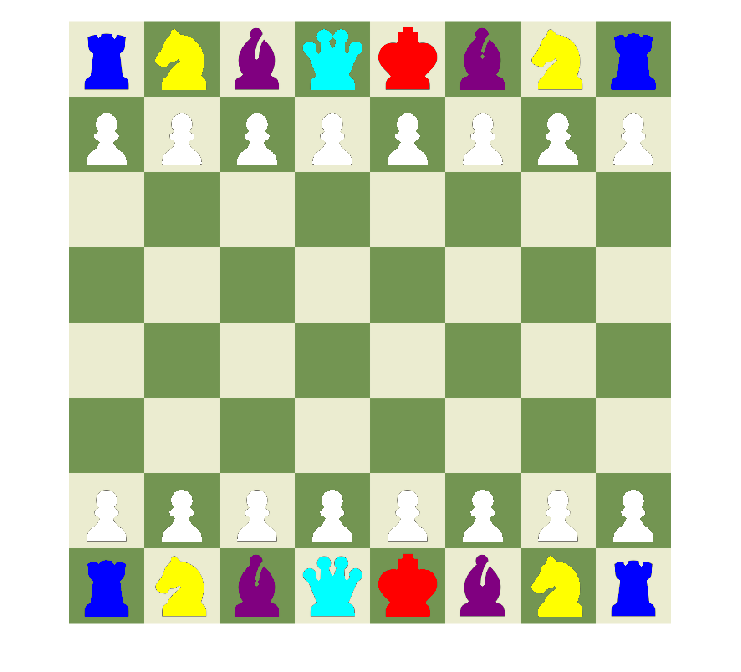

% Convertir coloredImage a uint8
coloredImage_uint8 = im2uint8(coloredImage);

% Realizar la resta
test = board_full_reduced + coloredImage_uint8;

% Mostrar la imagen resultado
imshow(test);

Hay que tener en cuenta que las regiones coloreadas salen de una imagen que ha sido procesada con la operación morfológica close por lo que no encaja exacta con la imagen original.

### CONCLUSIONES

- Se ha de tener en cuenta el color de la pieza (negro/blanco) al estar sobre una casilla (negra/blanca) a la hora de binarizar.

- Las operaciones morfológicas se realizan después de haber rellenado la región con `imfill()`

- Incluso para piezas del mismo tipo y color, las áreas calculadas con `regionprops() `dan resultados ligeramente distintos, que deben ser acotados.

- Utilizar imágenes que contienen distintos casos (piezas de ambos colores sobre casillas de ambos colores), hace el procesamiento más eficiente que si se analizase cada pieza por separado.

- Teniendo piezas con áreas muy parecidas (alfil y torre) al aplicar un cierre los agujeros se cierran y las áreas se distinguen mejor.

- Tener intervalos de áreas sin ninguna intersección hace que la clasificación acierte ante cualquier imagen propuesta en los ejemplos.

### Prueba con otras imágenes:

- Magnus Caerlesen (2581ptos.) vs Sipke Erns (2521ptos.) 

Date: 2004.01.24

Result: 1-0

Event: It (cat.9)

Site: Wijk aan Zee (Netherlands)

magnus_sipke = imread("magnus_sipke.png");
brush = strel('disk', 2);

[stats, labeled_image, num_pieces] = pieceClassifier(brush,magnus_sipke);

Y su representación:

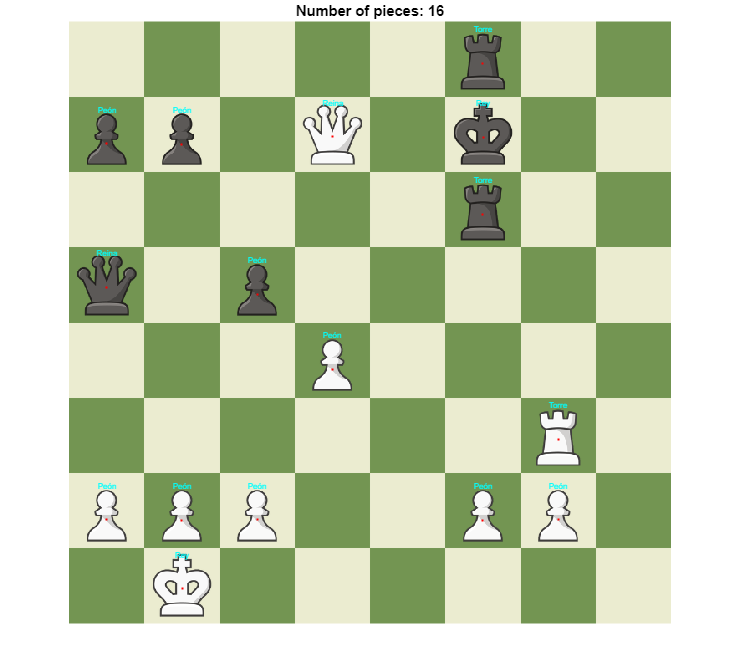

% Mostrar la imagen
imshow(magnus_sipke);
title(['Number of pieces: ', num2str(num_pieces)]);
hold on; % Mantener la imagen actual para dibujar sobre ella

% Iterar a través de cada región para plotear los centroides y los nombres de las piezas
for k = 1:num_pieces
        % Marcar el centroide
        plot(stats(k).Centroid(1), stats(k).Centroid(2), 'r.', 'MarkerSize', 5);
        
        % Añadir el nombre de la pieza al centroide
        text(stats(k).Centroid(1), stats(k).Centroid(2)-35, stats(k).Pieza, 'Color', 'cyan', ...
             'FontSize', 6, 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom');
end
    
hold off; % Liberar la figura

- Anatoly Kasparov vs Igor V Ivanov

Date: 1979.??.??

Result: 1-0

Event: Olympiad URS

Site: Moscow (Russia)

kasparov_ivanov = imread("kasparov_ivanov.png");
brush = strel('disk', 2);

[stats, labeled_image, num_pieces] = pieceClassifier(brush,kasparov_ivanov);

Y su representación:

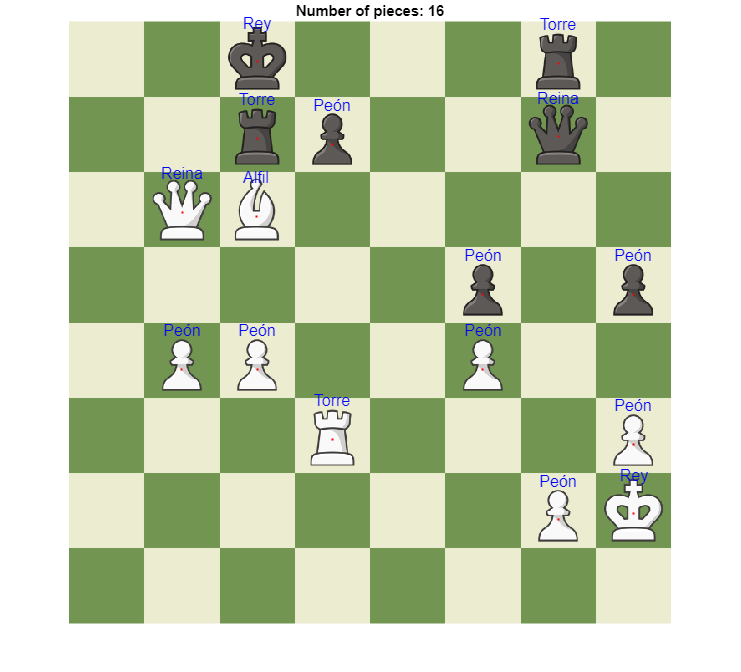

% Mostrar la imagen
imshow(kasparov_ivanov);
title(['Number of pieces: ', num2str(num_pieces)]);
hold on; % Mantener la imagen actual para dibujar sobre ella

% Iterar a través de cada región para plotear los centroides y los nombres de las piezas
for k = 1:num_pieces
        % Marcar el centroide
        plot(stats(k).Centroid(1), stats(k).Centroid(2), 'r.', 'MarkerSize', 5);
        
        % Añadir el nombre de la pieza al centroide
        text(stats(k).Centroid(1), stats(k).Centroid(2)-35, stats(k).Pieza, 'Color', 'blue', ...
             'FontSize', 12, 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom');
end
    
hold off; % Liberar la figura

- Anruki vs phrill

Date: 02.11.2024

Result: 1-0

Site: chess.com

ana_phrill = imread("ana_phrill.png");
brush = strel('disk', 2);

[stats, labeled_image, num_pieces] = pieceClassifier(brush,ana_phrill);

Y su representación:

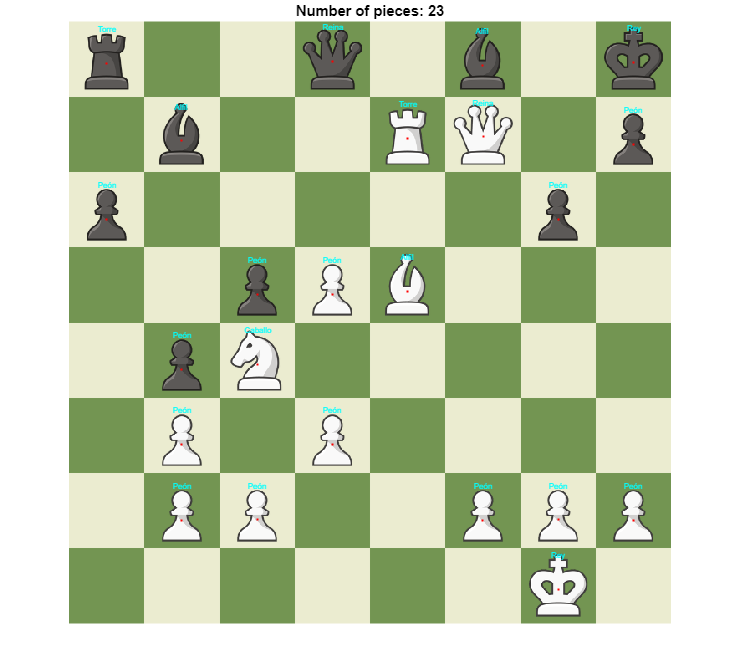

% Mostrar la imagen
imshow(ana_phrill);
title(['Number of pieces: ', num2str(num_pieces)]);
hold on; % Mantener la imagen actual para dibujar sobre ella

% Iterar a través de cada región para plotear los centroides y los nombres de las piezas
for k = 1:num_pieces
        % Marcar el centroide
        plot(stats(k).Centroid(1), stats(k).Centroid(2), 'r.', 'MarkerSize', 5);
        
        % Añadir el nombre de la pieza al centroide
        text(stats(k).Centroid(1), stats(k).Centroid(2)-35, stats(k).Pieza, 'Color', 'cyan', ...
             'FontSize', 6, 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom');
end
    
hold off; % Liberar la figura

Para los 3 ejemplos, clasifica todas las piezas correctamente.